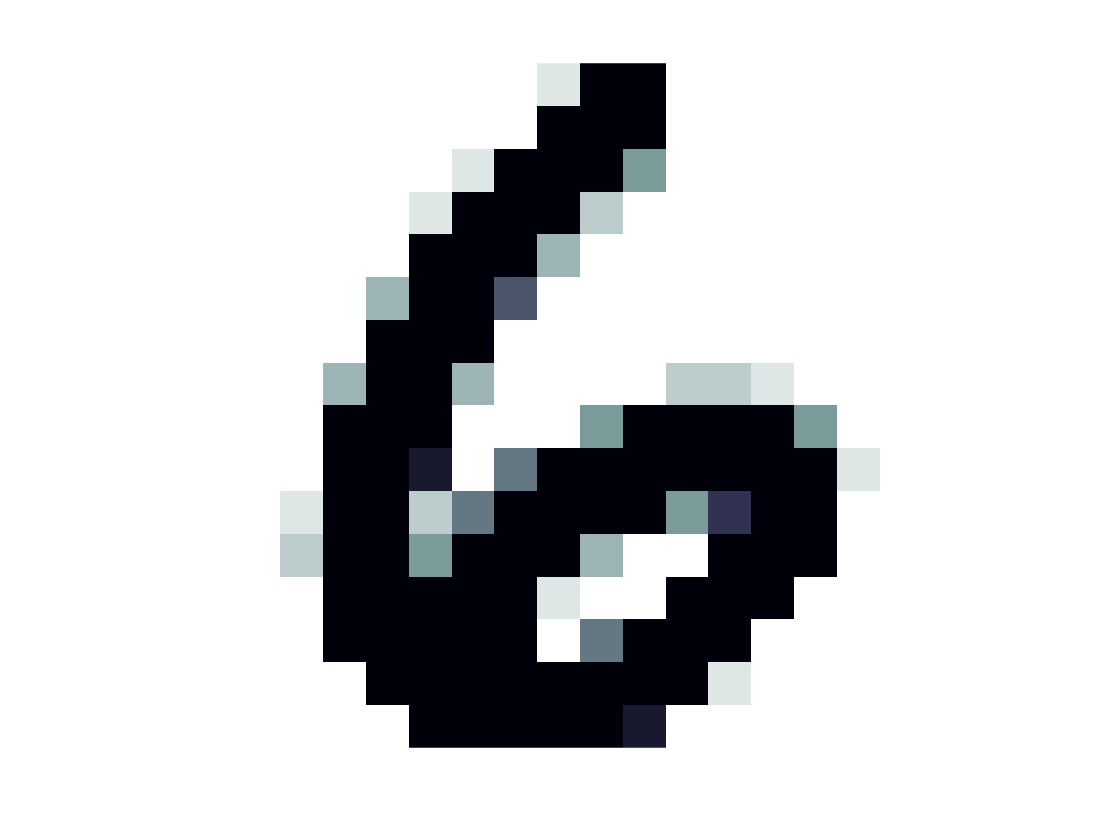

clear
load zipdata.mat

% azip -> Training data
% dzip -> Result for training data
% testzip -> Test data
% dtest -> Result for test data

% Assignment: Implement the tangent distance classifier

% Att göra: 
% Blurra bilderna för bättre resultat
% För att ta bort de gråa områderna/bakgrunderna

e = testzip(:,:,9);
p = azip(:,:,1);

ima(e)

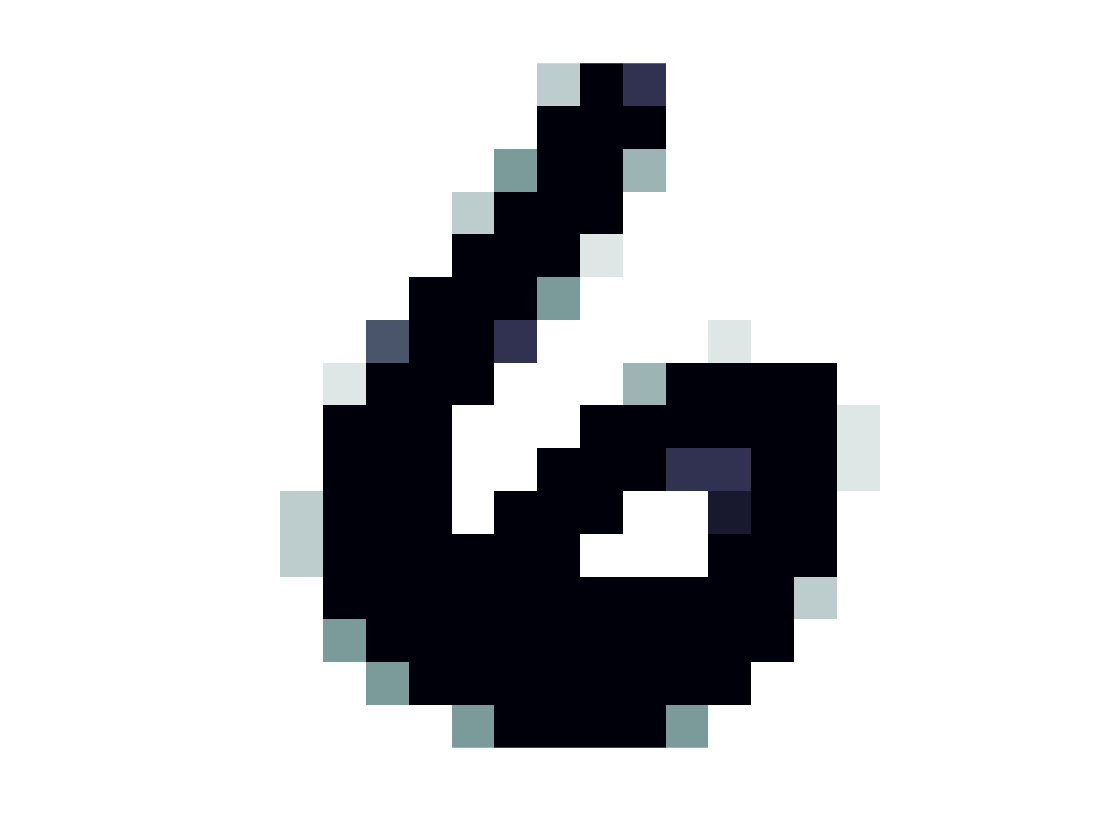

figure
ima(p)


% Padding white border around to be able to calculate the corners and edges
Tp = calcTransformMatrix(p);
Te = calcTransformMatrix(e);

A = [-Tp Te];
b = reshape(p, 256, 1) -reshape(e, 256,1);
alpha = A\b;

norm(b-A*alpha)

ans = 3.1959